# 4-6-2016 - Multisubject Anova Analysis 

close all;clear all;clc
Z_Constants;
SUB_DIR = fullfile(myGetenv('subject_dir'));
OUTPUT_DIR = fullfile(myGetenv('OUTPUT_DIR'));

anovaBetaMags5 = [];
anovaBetaMags3 = [];
anovaBetaMags1 = [];
anovaBetaBase = [];
anovaBetaSID = {};

for i = 2:length(SIDS)
    sid = SIDS{i}
    switch sid
        case 'd5cd55'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','d5cd55epSTATSsig'))
            stims = [54 62];
            goods = [35 36 37 44 45 46 52 53 55 60 61 63];
            
            betaChan = 53;
        case 'c91479'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','c91479epSTATSsig'))
            betaChan = 64;
            stims = [55 56];
            goods = [38 39 40 46 47 48 62 64];
            
            
        case '7dbdec'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','7dbdecepSTATSsig'))
            stims = [11 12];
            goods = [4 5 10 13 21 22 23];
            
            betaChan = 4;
        case '9ab7ab'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','9ab7abepSTATSsig'))
            betaChan = 51;
            stims = [59 60];
            goods = [42 43 50 51 52 53 57 58];
            
        case '702d24'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','702d24epSTATSsig'))
            betaChan = 5;
            stims = [13 14];
            %                     goods = 5;
            goods = [4 5 6 12 20 21 22];
            
        case 'ecb43e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','ecb43eepSTATSsig'))
            dataForAnova{64} = [];
            CCEPbyNumStim{64} = [];
            
            betaChan = 55;
            goods = [55 63 54 46 47 48 46];
            stims = [56 64];
            
        case '0b5a2e'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2eepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            
        case '0b5a2ePlayback'
            load(fullfile(OUTPUT_DIR,'BetaTriggeredStim','CSNESiteVisit','0b5a2ePlaybackepSTATSsig'))
            betaChan = 31;
            stims = [22 30];
            goods = [12 13 14 15 16 21 23 31 32 39 40];
            
    end
    
    
    tBmat =[];
    t1mat = [];
    t2mat = [];
    t3mat = [];
    chan = betaChan;
    
    % figure out number of test conditions
    numTypes = length(CCEPbyNumStim{1});
    
    if strcmp(sid,'0b5a2e') || strcmp(sid,'0b5a2ePlayback') || strcmp(sid,'ecb43e')
        nullType = 3;
        
    else
        nullType = NaN;
    end
    
    tBmat =[];
    t1mat = [];
    t2mat = [];
    t3mat = [];
    
    % cells, rather than stacked, of responses for given num stimuli
    tempBaseTotal = {};
    tempResp1Total = {};
    tempResp2Total = {};
    tempResp3Total = {};
    tempRespNull = {};
    
    % for each channel, a single stacked vector of all of the responses for a given number of stimuli
    tB = [];
    t1 = [];
    t2 = [];
    t3 = [];
    
    
    for i = 1:numTypes
        
        if i ~= nullType
            tempMag = dataForAnova{chan}{i}{1};
            tempLabel = dataForAnova{chan}{i}{2};
            tempKeeps = dataForAnova{chan}{i}{3};
            
            tempBase = tempMag(tempLabel(tempKeeps)==0);
            tempResp1 = tempMag(tempLabel(tempKeeps)==1);
            tempResp2 = tempMag(tempLabel(tempKeeps)==2);
            tempResp3 = tempMag(tempLabel(tempKeeps)==3);
            
            tempBaseTotal{i} =  tempBase;
            tempResp1Total{i} =  tempResp1;
            tempResp2Total{i} =  tempResp2;
            tempResp3Total{i} =  tempResp3;
            
            tB = [tB tempBase];
            t1 = [t1 tempResp1];
            t2 = [t2 tempResp2];
            t3 = [t3 tempResp3];
            
        elseif i == nullType && strcmp(sid,'ecb43e') == 0
            tempMag = dataForAnova{chan}{i}{1};
            tempLabel = dataForAnova{chan}{i}{2};
            tempKeeps = dataForAnova{chan}{i}{3};
            
            tempBase = tempMag(tempLabel(tempKeeps)==0);
            tempResp1 = tempMag(tempLabel(tempKeeps)==1);
            
            tempRespNull{i} = tempResp1;
            
        end
    end
    lengthToRep = length(t3);
    sidString = repmat(sid,lengthToRep,1);
    sidCell = cellstr(sidString)';
    anovaBetaMags5 = [anovaBetaMags5 t3];
    anovaBetaMags3 = [anovaBetaMags3 t2];
    anovaBetaMags1 = [anovaBetaMags1 t1];
    anovaBetaBase = [anovaBetaBase tB] ;
    anovaBetaSID = [anovaBetaSID{:} sidCell];
    
    
    
    
end

sid = d5cd55

sid = c91479

sid = 7dbdec

sid = 9ab7ab

sid = 702d24

sid = ecb43e

sid = 0b5a2e

sid = 0b5a2ePlayback

p = 0

tbl =     'Source'    'SS'            'df'      'MS'            'F'           'Prob>F'
    'Groups'    [3.0290e+06]    [   7]    [4.3272e+05]    [873.7296]    [     0]
    'Error'     [1.0712e+06]    [2163]    [  495.2572]            []          []
    'Total'     [4.1003e+06]    [2170]              []            []          []


stats =     gnames: {8x1 cell}
         n: [39 215 479 370 347 545 88 88]
    source: 'anova1'
     means: [128.1727 76.5386 94.1203 41.2231 103.6209 153.1982 119.9490 111.9235]
        df: 2163
         s: 22.2544


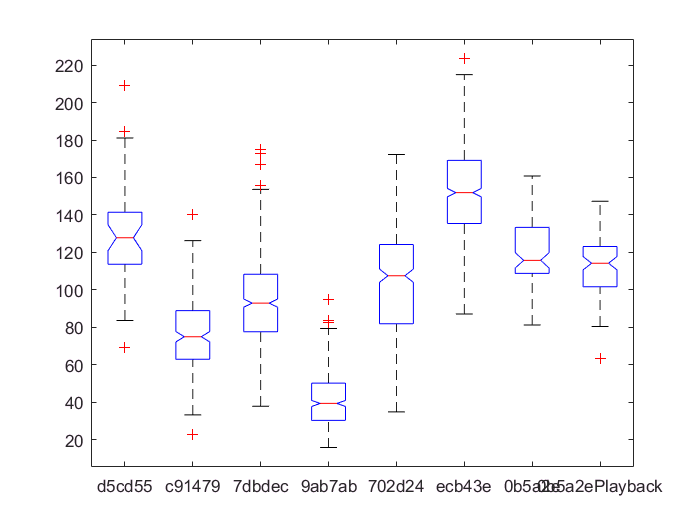

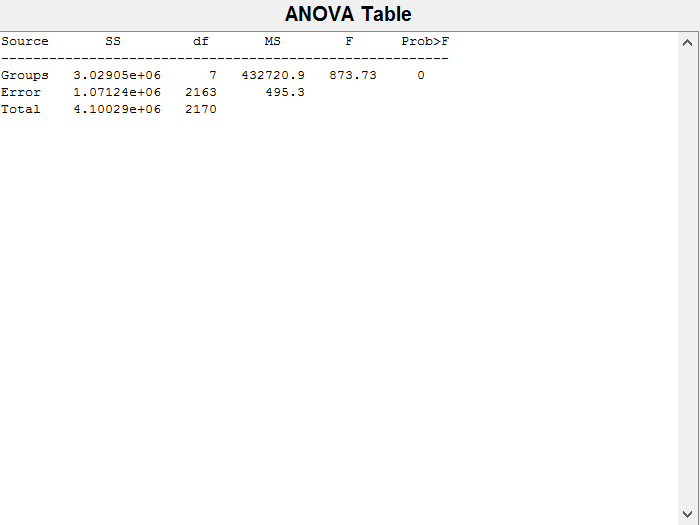

    [p,tbl,stats] = anova1(anovaBetaMags5,anovaBetaSID)

    [c,m,h,gnames] = multcompare(stats);


The expression to the left of the equals sign is not a valid target for an assignment.
